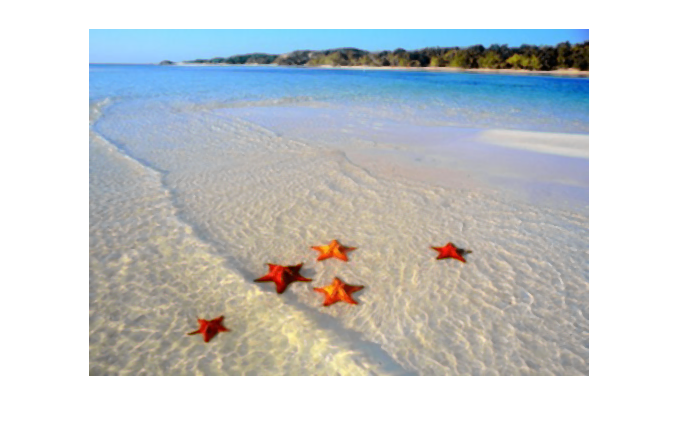

im = imread ("images\starfish_5.jpg");
% im = rgb2gray(im);
im = medfilt3(im);
imshow(im);

IsLowContrast(im);

theRange2 = 79.8455

theMeanMStd = 127.2204

theMeanPStd = 207.0659

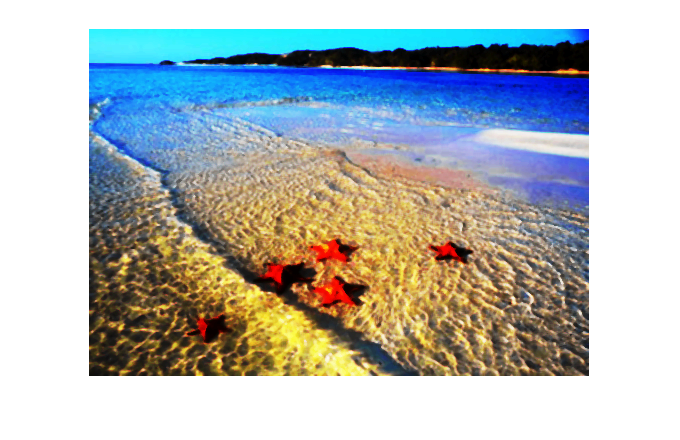


imeq = histeq(im);
imshow(imeq);

IsLowContrast(imeq);

theRange2 = 149.4309

theMeanMStd = 52.7382

theMeanPStd = 202.1691

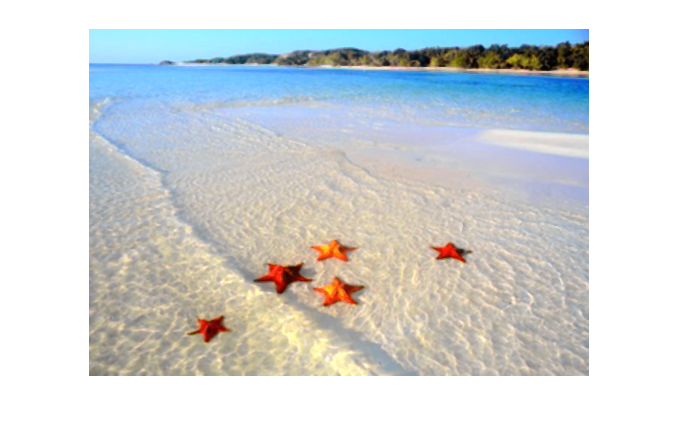


im = im * 1.1;
imshow(im);

IsLowContrast(im);

LOW CONTRAST


theRange2 = 85.4412

theMeanMStd = 140.5569

theMeanPStd = 225.9980

function bool = IsLowContrast(im)
% Low range or mean is > 200 || < 50 ;
RANGE = 75;
LOW = 40;
HIGH = 215;

theMin = min(im(:));
theMax = max(im(:));
theRange = theMax - theMin;
theMean = mean(im(:));
theStd = std2(im(:));
theMeanPStd = theMean + theStd;
theMeanMStd = theMean - theStd;
theRange2 = theMeanPStd - theMeanMStd;

bool = 0;
% if ((theRange <= RANGE) || (theMeanMStd > HIGH || theMeanPStd < LOW))
% if (theRange2 < RANGE && (theMeanMStd > HIGH || theMeanPStd < LOW)) 
if (theRange2 < RANGE || (theMeanMStd < LOW|| theMeanPStd > HIGH))  
% if ((theMeanMStd < LOW|| theMeanPStd > HIGH))
    bool = 1;
    disp("LOW CONTRAST");
end
    theRange2
    theMeanMStd
    theMeanPStd
end